# LAB 2: FREQUENCY DOMAIN AND TRANSFER FUNCTIONS

%---------------------------------------
% Fill in your student Name and ID.
Students.Name = 'Seyed Yazdan Zinati';
Students.ID = '260928077';
%---------------------------------------

## **0. Objectives**

The purpose of this lab is to overview the basic `MATLAB` functions in linear systems and control. At the end of this lab, you will be able to plot the step and impulse response of a rational transfer function and analyze with first and second order transfer functions.

## **1. Introduction**

The first step in the design of a control system is to identify a mathematical model of the system. Such a mathematical model could be derived either from physical laws or from experimental data. For Linear Time Invariant (LTI) systems, we only need to identify the impulse response or it's frequency-domain representation: the transfer function.

In this lab, we introduce how to model transfer functions in `MATLAB`. There are various methods to define a transfer function in `MATLAB`. As an example, suppose we have a system described by the following constant coefficient linear differential equation:


$$ a_2 \displaystyle \frac{d^2 y(t)}{dt} + a_1 \displaystyle \frac{d
y(t)}{dt} + a_0 y(t) = b_1 \displaystyle \frac{d u(t)}{dt} + b_0 u(t) $$


We know that the transfer function of this system is


$$ H(s) = \displaystyle \frac{Y(s)}{U(s)} = \displaystyle \frac{b_1 s +
b_0}{a_2 s^2 + a_1 s + a_0} $$


Suppose $a_0=2$, $a_1=3$, $a_2=1$, $a_3=1$, $b_0=2$, $b_1=2$.

The first method of specifying the function is to literally type out this expression. We first define the symbol $s$ using the `tf` function and then define the transfer function $H$ in terms of $s$. For example:

% Assign values to the coefficients
a2 = 1;
a1 = 3;
a0 = 2;
b1 = 2;
b0 = 6;
% Define s symbolically in frequency domain
s = tf('s');

Then we can directly define the transfer function as follows.

H1 = (b1 * s + b0) / (a2 * s^2 + a1 * s + a0)

H1 =
 
     2 s + 6
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.



The second method is to directly specify the polynomials of the numerator and the denominators.

% Define the numerator
num = [b1, b0];
% Define the denominator
den = [a2, a1, a0];
% Define the transfer function
H2 = tf(num, den)

H2 =
 
     2 s + 6
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.



Another way to define the transfer function is to use the gain, poles and zeros. Let's reconsider the above transfer function in pole-zero form.


$$ H(s) = 2 \displaystyle \frac{s+2}{(s+1)(s+2)} $$


We can specify the transfer function in the pole zero form using the following code.

k = 2; % The gain
z = [-3]; % The set of zeros
p = [-1, -2]; % The set of poles
H3 = zpk(z, p, k) % Define the transfer function

H3 =
 
    2 (s+3)
  -----------
  (s+1) (s+2)
 
Continuous-time zero/pole/gain model.



There are other forms of using the `zpk` function. Use `doc zpk` for more information.

It is possible to identify the poles and zeros of a **rational** transfer function using `tf2zp`:

[z, p, k] = tf2zp(num, den)

z = -3

p =     -2
    -1


k = 2

## **2. Plotting Impulse and Step Responses**

To plot the impulse response of a transfer function, one can use `impulse(sys)`. To plot the step response, one can use `step(sys)`. As an example, we plot the impulse and step responses of the system defined in the previous section:

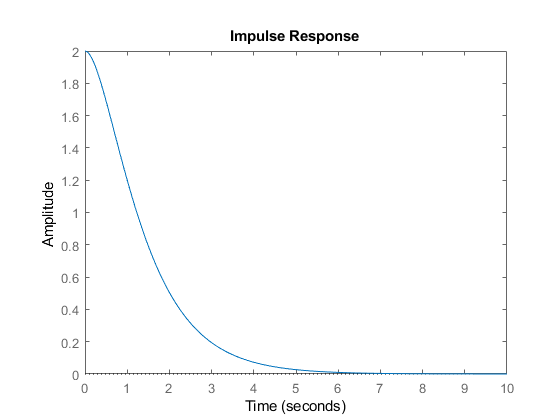

T = 10; % Final time value
figure;
impulse(H1, T)

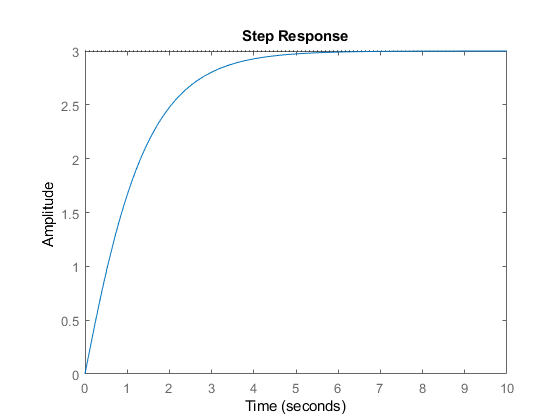

figure;
step(H1, T)

To find the poles and zeros of a transfer function, use `pole(system)` and `zero(systems)`. To plot the pole-zero plot, use `pzplot(system)`. For example, for the system defined above, the poles are

pole(H1)

ans =     -2
    -1


and the zeros are

zero(H1)

ans = -3

We can show the pole-zero plot using

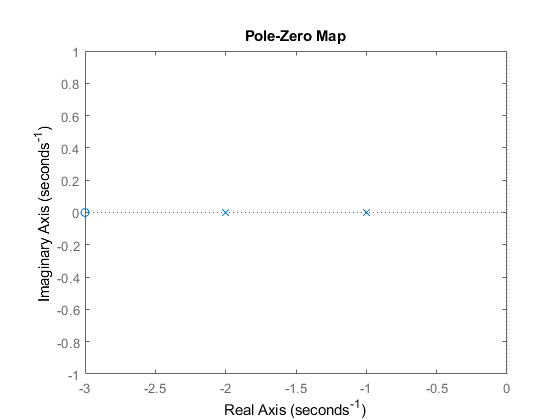

pzplot(H1)

## **Interconnecting systems**

To get the transfer function for two systems connected in feedback, use

H = feedback(H1, H2) % Feedback or closed-loop interconnection of systems

H =
 
     2 s^3 + 12 s^2 + 22 s + 12
  --------------------------------
  s^4 + 6 s^3 + 17 s^2 + 36 s + 40
 
Continuous-time transfer function.



Use `doc feedback` for more information.

## **3. System Response characteristics**

Consider the following step response of an unknown transfer function.

<<fig_lab02_secondorder.png>>

Depending on the location of the zeros and poles in a transfer function, it is possible to define a system response by the following characteristics:

- Rise time ($t_r$): is the time it takes the system to reach to rise from 10% to 90% of its final value.

- Peak time ($t_p$): is the time until the response hits its maximum overshoot.

- Overshoot ($M_p$): is the peak value of the step response of the system.

- Settling time ($t_s$): is the time for the response to settle within $\pm \Delta$ % of its final value.

It is possible to find these values in `MATLAB` given a transfer function. `stepinfo(sys)` computes the step-response characteristics for a dynamic system model. For example

stepinfo(H1)

ans = struct with fields:
        RiseTime: 2.4200
    SettlingTime: 4.1960
     SettlingMin: 2.7023
     SettlingMax: 2.9974
       Overshoot: 0
      Undershoot: 0
            Peak: 2.9974
        PeakTime: 7.3222


## *Question 1 (2 marks)*

For $\xi = \{0.25, 0.75, 1, 2\}$, plot the step response **(for 25 sec)** and identify the characteristics of the transient response of the following system


$$ G(s) = \displaystyle \frac{1}{s^2+2 \xi s + 1} $$


%------------------------------------
% defining the transfer function 

xi = 0.25;  
% define numerator and denominator
num = 1;
den = [1, 2*xi, 1];
G1 = tf(num, den)

G1 =
 
         1
  ---------------
  s^2 + 0.5 s + 1
 
Continuous-time transfer function.



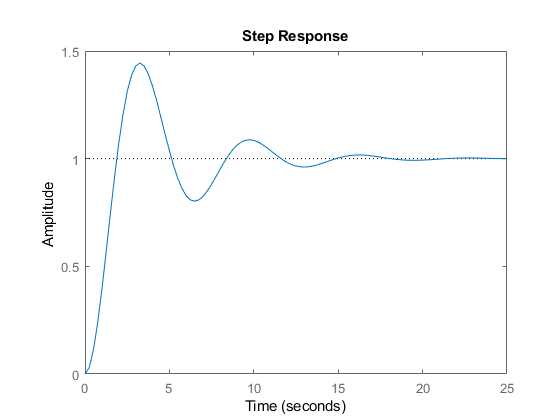


%------------------------------------
% plotting the step response

% final time value
T = 25;
figure;
step(G1, T)


%------------------------------------
% identifying the characteristics 
% of the transient response
stepinfo(G1)

ans = struct with fields:
        RiseTime: 1.2687
    SettlingTime: 14.1159
     SettlingMin: 0.8027
     SettlingMax: 1.4432
       Overshoot: 44.3235
      Undershoot: 0
            Peak: 1.4432
        PeakTime: 3.3157


%------------------------------------
% defining the transfer function 

xi = 0.75;  
% define numerator and denominator
num = 1;
den = [1, 2*xi, 1];
G2 = tf(num, den)

G2 =
 
         1
  ---------------
  s^2 + 1.5 s + 1
 
Continuous-time transfer function.



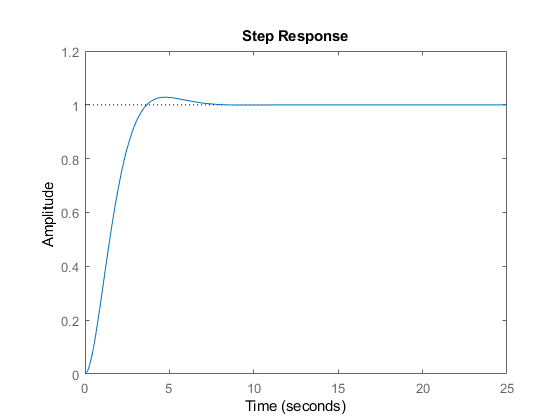


%------------------------------------
% plotting the step response

% final time value
T = 25;
figure;
step(G2, T)


%------------------------------------
% identifying the characteristics 
% of the transient response
stepinfo(G2)

ans = struct with fields:
        RiseTime: 2.2884
    SettlingTime: 5.7426
     SettlingMin: 0.9049
     SettlingMax: 1.0284
       Overshoot: 2.8369
      Undershoot: 0
            Peak: 1.0284
        PeakTime: 4.7280


%------------------------------------
% defining the transfer function 

xi = 1;  
% define numerator and denominator
num = 1;
den = [1, 2*xi, 1];
G3 = tf(num, den)

G3 =
 
        1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.



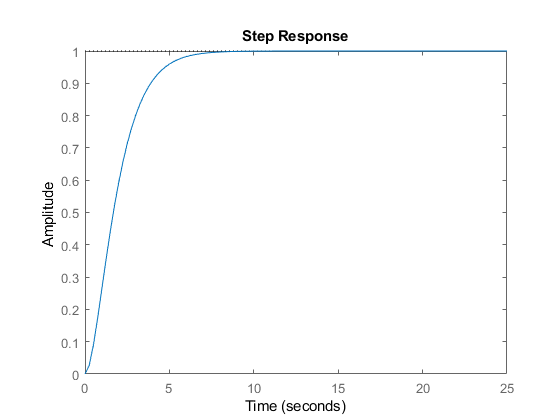


%------------------------------------
% plotting the step response

% final time value
T = 25;
figure;
step(G3, T)


%------------------------------------
% identifying the characteristics 
% of the transient response
stepinfo(G3)

ans = struct with fields:
        RiseTime: 3.3579
    SettlingTime: 5.8339
     SettlingMin: 0.9000
     SettlingMax: 0.9994
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9994
        PeakTime: 9.7900


%------------------------------------
% defining the transfer function 

xi = 2;  
% define numerator and denominator
num = 1;
den = [1, 2*xi, 1];
G4 = tf(num, den)

G4 =
 
        1
  -------------
  s^2 + 4 s + 1
 
Continuous-time transfer function.



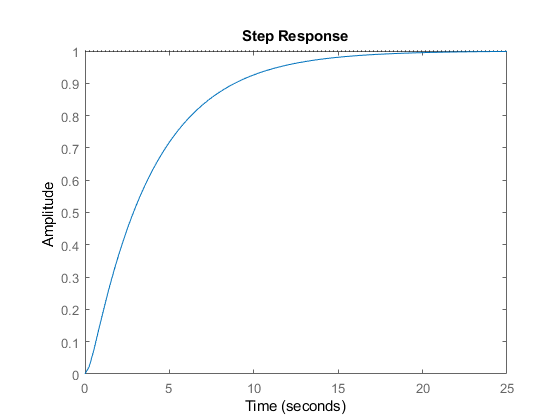


%------------------------------------
% plotting the step response

% final time value
T = 25;
figure;
step(G4, T)


%------------------------------------
% identifying the characteristics 
% of the transient response
stepinfo(G4)

ans = struct with fields:
        RiseTime: 8.2308
    SettlingTime: 14.8789
     SettlingMin: 0.9017
     SettlingMax: 0.9993
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9993
        PeakTime: 27.3269


## *Question 2 (4 marks)*

Consider the following open-loop unstable system.


$$ Q(s) = \displaystyle \frac{s+1}{s(s-1)(s+6)} $$


A constant gain $k$ (controller) is used to stabilize this system. For different values of $k \in \{10,\ 20,\ 50,\ 100\}$, plot the step response **(for 15 seconds)** of the closed-loop system and identify its characteristics using `stepinfo`.

<<fig_lab02_closedLoop.png>>

% Define the transfer function
gain = 1;
z = [-1];
p = [0, 1, -6];

transferFunction1 = zpk(z, p, gain) 

transferFunction1 =
 
      (s+1)
  -------------
  s (s-1) (s+6)
 
Continuous-time zero/pole/gain model.



k1 = 10;
connectedTransferFunction1 = feedback(transferFunction1, k1)

connectedTransferFunction1 =
 
               (s+1)
  --------------------------------
  (s+4.603) (s^2 + 0.397s + 2.173)
 
Continuous-time zero/pole/gain model.



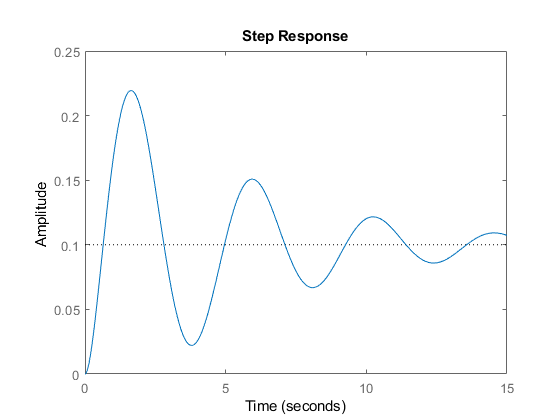


% plot the step response 
T1 = 15;
figure;
step(connectedTransferFunction1, T1)


%------------------------------------
% identifying the characteristics 
% of the response
stepinfo(connectedTransferFunction1)

ans = struct with fields:
        RiseTime: 0.4424
    SettlingTime: 21.2506
     SettlingMin: 0.0221
     SettlingMax: 0.2194
       Overshoot: 119.3930
      Undershoot: 0
            Peak: 0.2194
        PeakTime: 1.6408


k2 = 20;
connectedTransferFunction2 = feedback(transferFunction1, k2)

connectedTransferFunction2 =
 
               (s+1)
  --------------------------------
  (s+2.579) (s^2 + 2.421s + 7.756)
 
Continuous-time zero/pole/gain model.



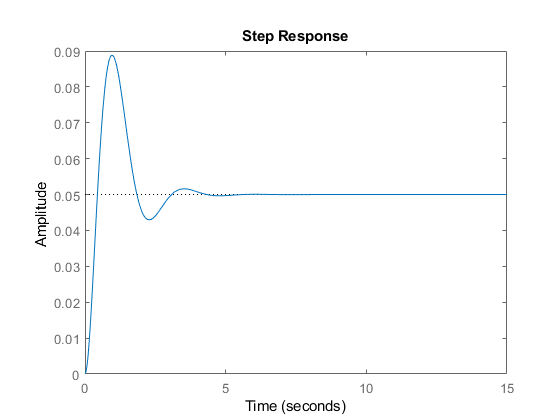


% plot the step response 
T1 = 15;
figure;
step(connectedTransferFunction2, T1)


%------------------------------------
% identifying the characteristics 
% of the response
stepinfo(connectedTransferFunction2)

ans = struct with fields:
        RiseTime: 0.2989
    SettlingTime: 3.8974
     SettlingMin: 0.0430
     SettlingMax: 0.0889
       Overshoot: 77.7158
      Undershoot: 0
            Peak: 0.0889
        PeakTime: 0.9644


k3 = 50;
connectedTransferFunction3 = feedback(transferFunction1, k3)

connectedTransferFunction3 =
 
               (s+1)
  --------------------------------
  (s+1.274) (s^2 + 3.726s + 39.25)
 
Continuous-time zero/pole/gain model.



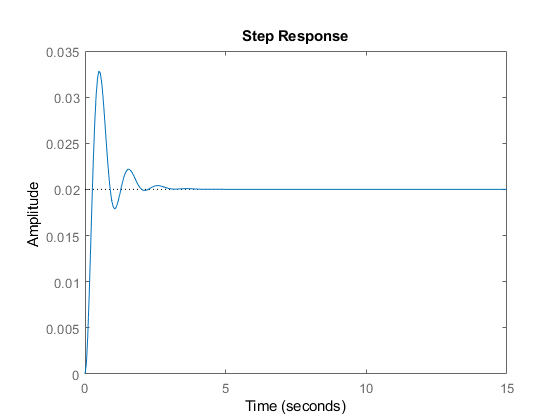


% plot the step response 
T1 = 15;
figure;
step(connectedTransferFunction3, T1)


%------------------------------------
% identifying the characteristics 
% of the response
stepinfo(connectedTransferFunction3)

ans = struct with fields:
        RiseTime: 0.1767
    SettlingTime: 2.6377
     SettlingMin: 0.0179
     SettlingMax: 0.0329
       Overshoot: 64.3033
      Undershoot: 0
            Peak: 0.0329
        PeakTime: 0.5062


k4 = 100;
connectedTransferFunction4 = feedback(transferFunction1, k4)

connectedTransferFunction4 =
 
               (s+1)
  --------------------------------
  (s+1.115) (s^2 + 3.885s + 89.67)
 
Continuous-time zero/pole/gain model.



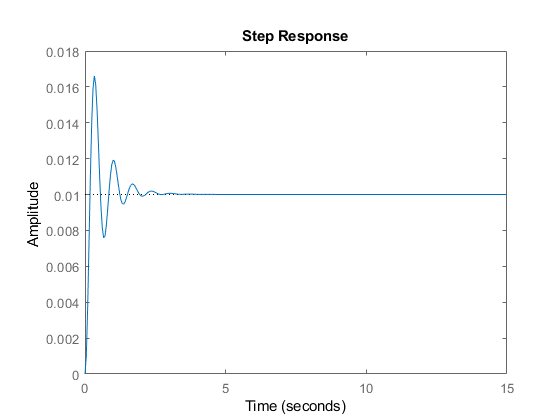


% plot the step response 
T1 = 15;
figure;
step(connectedTransferFunction4, T1)


%------------------------------------
% identifying the characteristics 
% of the response
stepinfo(connectedTransferFunction4)

ans = struct with fields:
        RiseTime: 0.1190
    SettlingTime: 1.8674
     SettlingMin: 0.0076
     SettlingMax: 0.0166
       Overshoot: 66.0662
      Undershoot: 0
            Peak: 0.0166
        PeakTime: 0.3303


## *Question 3 (4 marks)*

Consider the closed-loop transfer function in Question 2.


$$ T(s) = \displaystyle \frac{k Q(s)}{1 + k Q(s)} $$


We would like to approximate this system to a second order system of the form:


$$ G(s) = \displaystyle
\frac{\displaystyle\frac{k}{|p_3|}(s-z_1)}{(s-p_1)(s-p_2)} $$


- For $k = \{10,\ 20\}$, find $p_1$, $p_2$ and $p_3$, where $p_1$ and $p_2$ are the dominant poles (i.e., poles with the smallest absolute real values) and $p_3$ is the ineffective pole(i.e., the pole with the largest absolute real value).

- For $k = \{10,\ 20\}$, plot the step response of the new second order system for **15 sec** and identify its characteristics using `stepinfo`.

- For $k = \{10,\ 20\}$, compare the step response with those obtained in Question 2. What do you observe?

- 1)

% Find the pole(s) and zero(s) of the two transfer functions
%


%

Transfer functions with dominant poles

% k = 10
%

% k = 20
%

- 2)

% k = 10
%

% k = 20
%

- 3)

% k = 10
%

% k = 20
%

% [Answer here]